clear all
close all
Npt = 2^10; 
n = (-Npt/2:1:Npt/2 -1); 

ti = -20; 
tf = -ti; 
Ts = (tf - ti)/(Npt);  
t = n*Ts; 

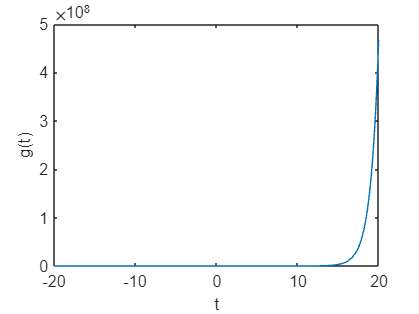

g = t*0; 

g = exp(t); % INSIRA AQUI A SUA FUNÇÃO g(t)

plot(t, g)
xlabel('t')
ylabel('g(t)')

Npt_v = 2^11;
vi = -0.05;
vf = -vi;
v_step = (vf - vi)/(Npt_v);
k = (-Npt_v/2:1:Npt_v/2 -1);
v = k*v_step;

G_DTFT = v*0; 

for u = 1:length(v)

    G_DTFT(u) = sum(g.*exp(-1i*2*pi*v(u)*n));

end 


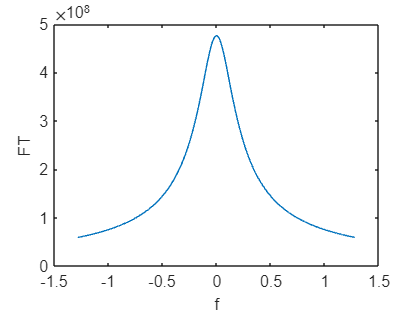

fs = 1/Ts;
f = v*fs;

G_FT = G_DTFT./fs;


plot(f, abs(G_FT))
xlabel('f')
ylabel('FT') 